# Práctica N°2 Control Biológico.

Autor: Tomás Vidal

### Notas

Para esta práctica se considera el mismo problema que se tenía en la práctica N°1.

## Preguntas

- Por qué la matriz $A\left(\xi \right)$ se calcula haciendo el Jacobiano?

- Se puede entregar el livescript en vez de un .m y un pdf? o el livescript hecho pdf?

- ¿Por qué no se corresponde la derivación analítica con la modelación? (se espera que $\Omega_2$ no sea un parámetro de los polos del observador, pero lo es)

# Problemas/Incisos

1) 

- A) Analice la observabilidad del proceso reducido linealizado. Considere dos escenarios, uno don- de se cuenta con medición de la FCE y otro donde se cuenta con la medición de la concentra- ción de microorganismos.

- B) Tomando uno de los escenarios en que el proceso sea observable, diseñe un observador expo- nencial para estimar el/los estados no medidos. Diseñe tanto por Luenberger como por Kal- man.

- C) Simule los observadores en un proceso continuo, tanto con el modelo reducido como con el completo. Analice los resultados.

2)

- A) Tomando una reducción del modelo que conste de una única reacción y tenga al menos 3 estados, diseñe un observador asintótico basado en medición de biomasa.

- B) Simule el observador en un proceso continuo, tanto tomando como referencia al modelo reducido como al completo. Analice los resultados.

## Inciso A, observabilidad

Para analizar la observabilidad se emplea la matriz de observabilidad O (tiene que ser de rango completo para que sea observable).

     
$$O=$$

$$\left[\matrix{L \cr L A(\xi) \cr LA^2(\xi)}\right]$$


Para que O sea de rango completo, los vectores columna tienen que formar un espacio vectorial de orden 3.

### Matriz A

Para calcular $A\left(\xi \right)$ se considera el modelo en variable de estados.


$$
\left[
\begin{array}{c}
\dot{x} \\
\dot{s} \\
\dot{n} \\
\dot{p}
\end{array}
\right]
=
\left[
\begin{array}{c}
1 & 0 \\ 
-K_{s1} & -K_{s2} \\
-K_{N} & 0 \\
K_{p1}  & 1
\end{array}
\right]
*
\left[
\begin{array}{c}
x \\ s \\ n \\ p
\end{array}
\right]
- D * \left[
\begin{array}{c}
x \\ s \\ n \\ p
\end{array}
\right]

$$


Cuyas matrices son referenciadas como $\hat{\xi} =K*r\left(\xi \;\right)+D*\xi \;$

Pero para poder trabajar con un modelo de 2x2 y que las cuentas sean más fáciles, como se va a trabajar en la fase de producción de plástico, donde el nitrógeno (n) debe ser nulo para poder darse, se elimina ese estado del sistema, además como en la producción de plástico la biomasa  es la misma, se podría considerar constante, por lo que también se elimina ese estado, resultado en el siguiente modelo de orden reducido:


$$
\left[
\begin{array}{c}
\dot{s} \\
\dot{p}
\end{array}
\right]
=
\left[
\begin{array}{c}
-K_{s1} & -K_{s2} \\
K_{p1}  & 1
\end{array}
\right]
*
\left[
\begin{array}{c}
s \\ p
\end{array}
\right]
- D * \left[
\begin{array}{c}
s \\ p
\end{array}
\right]

$$


Se calcula A para este caso


$$A(\xi) = \left[
\begin{array}{c}
-K_{s1}\frac{dr_x}{ds}-D & -K_{s2}\frac{dr_x}{dp} \\
K_{p1}\frac{dr_p}{ds}  & \frac{dr_p}{dp}-D
\end{array}
\right] = 
\left[
\begin{array}{c}
-K_{s1}\frac{dr_x}{ds}-D & 0 \\
K_{p1}\frac{dr_p}{ds}  & -D
\end{array}
\right]$$


(calculé las derivadas a "mano")


$$A(\xi)=\left[
\begin{array}{c}
-K_{s1} (\frac{x.\mu_{max}n}{K_n+n})(\frac{1}{K_s+s+\frac{s^2}{K_{is}}})(1-\frac{s-\frac{2s^2}{K_{is}}}{K_s+s+\frac{s^2}{K_{is}}}) -D & 0 \\
K_{p1}(x.q_{pmax}\frac{K_{ipn}}{K_{ipn}+n})(\frac{3s^2}{K_{ips}}+2s+K_{ps}) & -D
\end{array}
\right]$$


Considero que el estado que mido es el sustrato, por lo que tengo una matriz L = [1 0], entonces la matriz O es:


$$O=\left[
\begin{array}{c}
1 & 0 \\
-K_{s1} (\frac{x\mu_{max}n}{K_n+n})(\frac{1}{K_s+s+\frac{s^2}{K_{is}}})(1-\frac{s-\frac{2s^2}{K_{is}}}{K_s+s+\frac{s^2}{K_{is}}}) -D & 0 \\
\end{array}
\right]$$


Cuyo rango es 1, por lo que no sería observable, pero si tomo L = [0 1]


$$O=\left[
\begin{array}{c}
0 & 1 \\
K_{p1}(x.q_{pmax}\frac{K_{ipn}}{K_{ipn}+n})(\frac{3s^2}{K_{ips}}+2s+K_{ps}) & -D
\end{array}
\right]$$


Que sí es de rango 2, por lo que si es observable. Por lo que se podría medir el plástico, y estimar el sustrato.

## Inciso B, diseño de observadores

### Observador de Luenberger

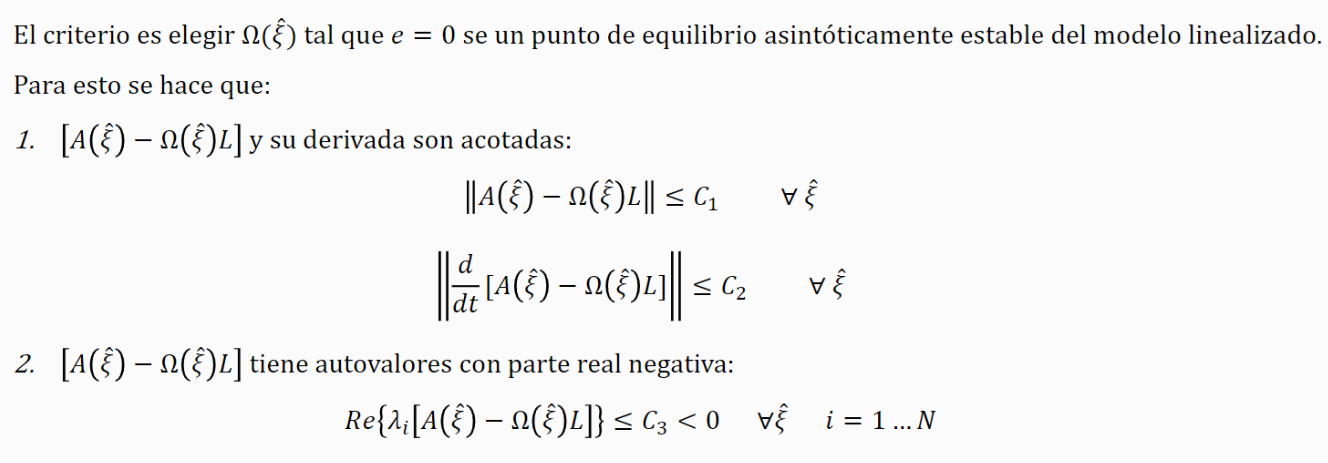

Si se cumplen 1 y 2 entonces el observador presenta estabilidad exponencial.

Se calculan los autovalores de $A\left(\hat{\xi} \right)-\Omega \left(\hat{\xi} \right)L$:


$$\left[
\begin{array}{c}
A_1 & 0 \\
A_2 & A_3 \\
\end{array}
\right]
-
\left[
\begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\end{array}
\right]
*
\left[
\begin{array}{c}
0 & 1
\end{array}
\right]
=
\left[
\begin{array}{c}
A_1 & -\Omega_1 \\
A_2 & A_3-\Omega_2 \\
\end{array}
\right]$$


De lo cual si se calculan los autovalores:


$$A_1 A_3 -A_1 \Omega {\;}_2 +A_2 \Omega {\;}_1 =0$$


Y si considero el caso cuando se tiene un batch (D=0), se puede ver en la matriz O que no sería observable ya que el rango termina siendo 1.

Por lo que se sólo se considera el caso con alimentación constante.

Para lo cual se obtienen las ganancias basadas en el resto de variables:

Primero calculo el polinomio característico de la matriz $A\left(\hat{\xi} \right)$


$$P\left(\lambda \right)=|\lambda {\textrm{II}}_{2\textrm{x2}} -A\left(\hat{\xi} \right)|=\left(\frac{3\Omega_1 K_{\textrm{P1}} q_{\max } }{K_{\textrm{ips}} }\right)\lambda^2 +2\lambda +K_{\textrm{ps}} +D^2 +D\Omega_2 =0$$


Y ahora el polinomio de polos deseados ($p_1$y $p_2$):


$$P\left(\lambda \right)=\left(\lambda -p_1 \right)\left(\lambda -p_2 \right)=\lambda^2 +\left(p_1 +p_2 \right)\lambda +\left(p_1 p_2 \right)$$


Entonces el vector Omega queda:


$$\Omega=\left[
\begin{array}{c}
p_1+p_2-2D \\
\\
\frac{D^2+D(p_1+p_2-2D)-p_1p_2}{x.q_{max}(\frac{3s^2}{K_{ips}}+2s+K_{ps})} \\
\end{array}
\right]$$


### Simulación de la estimación del sustrato

(se mide el plástico)

% addpath("c:\Users\tomii\Github\facultad\Control de Sistemas Biologicos\TP2")
DatosModelo
% savepath

sustratePerturbance.disturbancePercentage=300;
sustratePerturbance.perturbanceStart=10;
sustratePerturbance.perturbanceStop=15;

sim_hours = 20; % la cantidad de horas que se van a simular
timeStep = 0.001;

% Configuración de la simulación de Simulink
simConfig.StopTime = num2str(sim_hours);
simConfig.Solver = 'ode1';
simConfig.FixedStep = num2str(timeStep);

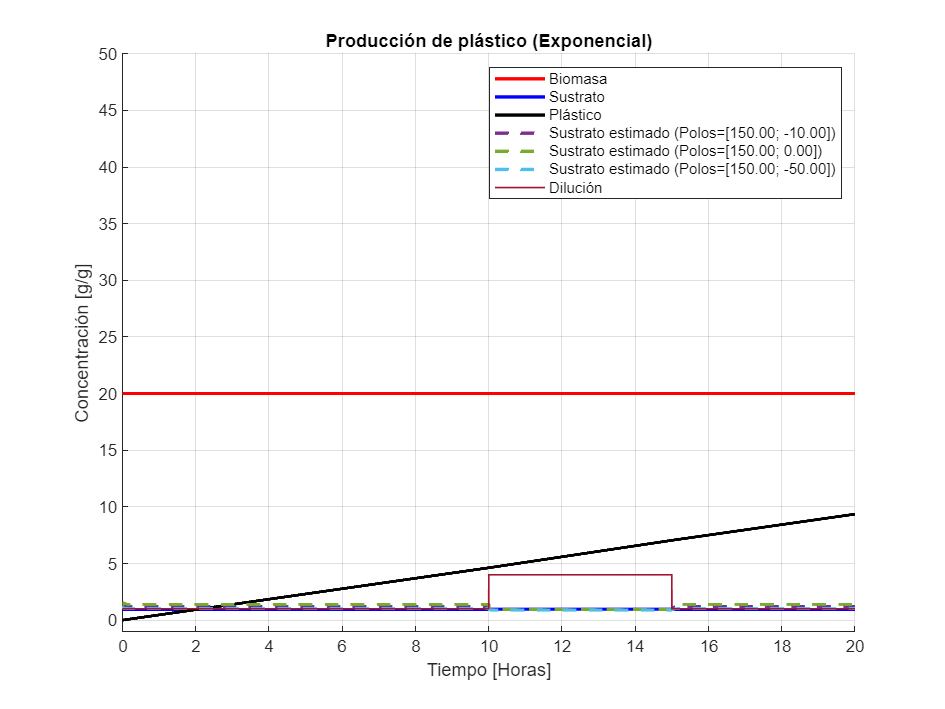

omegaParams.poles = [100, -10];

omegaParams.qmax =  qp_max;
omegaParams.kips = Kips;
omegaParams.kps = Kps;

estimatedModelParameters.K = [-ks2;1];
estimatedModelParameters.rp_params = modelParameters.rp_params;
estimatedModelParameters.Kipn = modelParameters.Kipn;

x0=20;
s0=1;
n0=0;
p0=0;
xi_in = [x0; s0; n0; p0];
D=20;
L=[0 1];

Poles={[150, -10], [150, 0], [150, -50]};

estimated_sustrate=cell(length(Poles));
error=cell(length(Poles));
MSE=cell(length(Poles));
for i=1:length(Poles)
    
    omegaParams.poles=Poles{i};

    sim_out = sim('TP2', simConfig);
    
    time = sim_out.tout;
    biomass = sim_out.x.Data;
    sustrate = sim_out.s.Data;
    nitrogen = sim_out.n.Data;
    plastic = sim_out.p.Data;
    mu = sim_out.mu.Data;
    qp = sim_out.qp.Data;
    volume = sim_out.v.Data;
    Do =  sim_out.Do.Data/D;
    estimated_states = sim_out.estimated_states.Data;
    % estimated_sustrate{i} = reshape(estimated_states(1,1,:), size(time));
    estimated_sustrate{i} = reshape(estimated_states(:,1), size(time));
    error{i}=(estimated_sustrate{i}-sustrate);
    MSE{i} = immse(estimated_sustrate{i}, sustrate);

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Producción de plástico (Exponencial)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
ylim([-1 50])
plot(time, biomass, 'r', 'LineWidth', 2);
plot(time, sustrate, 'b', 'LineWidth', 2);
plot(time, plastic, 'k', 'LineWidth', 2);
plot(time, estimated_sustrate{1}, '--', 'LineWidth', 2);
plot(time, estimated_sustrate{2}, '--', 'LineWidth', 2);
plot(time, estimated_sustrate{3}, '--', 'LineWidth', 2);
plot(time, Do, 'LineWidth', 1);

legend('Biomasa', 'Sustrato', 'Plástico', ...
    sprintf('Sustrato estimado (Polos=[%.2f; %.2f])', Poles{1}(1), Poles{1}(2)), ...
    sprintf('Sustrato estimado (Polos=[%.2f; %.2f])', Poles{2}(1), Poles{2}(2)), ...
    sprintf('Sustrato estimado (Polos=[%.2f; %.2f])', Poles{3}(1), Poles{3}(2)), ...
    'Dilución');

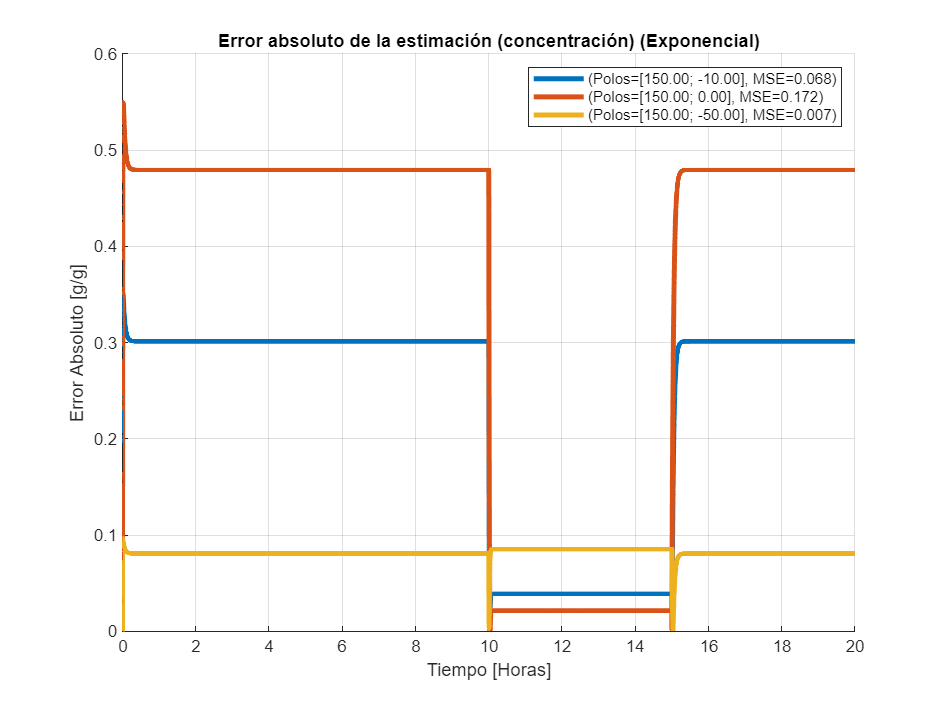


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error absoluto de la estimación (concentración) (Exponencial)');
xlabel('Tiempo [Horas]');
ylabel('Error Absoluto [g/g]');
plot(time, abs(error{1}), 'LineWidth', 3);
plot(time, abs(error{2}), 'LineWidth', 3);
plot(time, abs(error{3}), 'LineWidth', 3);

legend(sprintf('(Polos=[%.2f; %.2f], MSE=%.3f)', Poles{1}(1), Poles{1}(2), MSE{1}), ...
    sprintf('(Polos=[%.2f; %.2f], MSE=%.3f)', Poles{2}(1), Poles{2}(2), MSE{2}), ...
    sprintf('(Polos=[%.2f; %.2f], MSE=%.3f)', Poles{3}(1), Poles{3}(2), MSE{3}))


% Errores relativos
% fig = figure();
% set(fig,'Position',[0 0 800 600]);
% hold on; grid on;
% title('Error relativo de la estimación');
% xlabel('Tiempo [Horas]');
% ylabel('Error Relativo [%]');
% plot(time, error{1}*100/sustrate, 'LineWidth', 3);
% plot(time, error{2}*100/sustrate, 'LineWidth', 3);
% plot(time, error{3}*100/sustrate, 'LineWidth', 3);
% 
% legend(sprintf('(Omegas=[%d; %.2f], MSE=%.3f)', Omegas{1}(1), Omegas{1}(2), MSE{1}), ...
%     sprintf('(Omegas=[%d; %.2f], MSE=%.3f)', Omegas{2}(1), Omegas{3}(2), MSE{2}), ...
%     sprintf('(Omegas=[%d; %.2f], MSE=%.3f)', Omegas{3}(1), Omegas{2}(2), MSE{3}))

## Estimador de Kalman

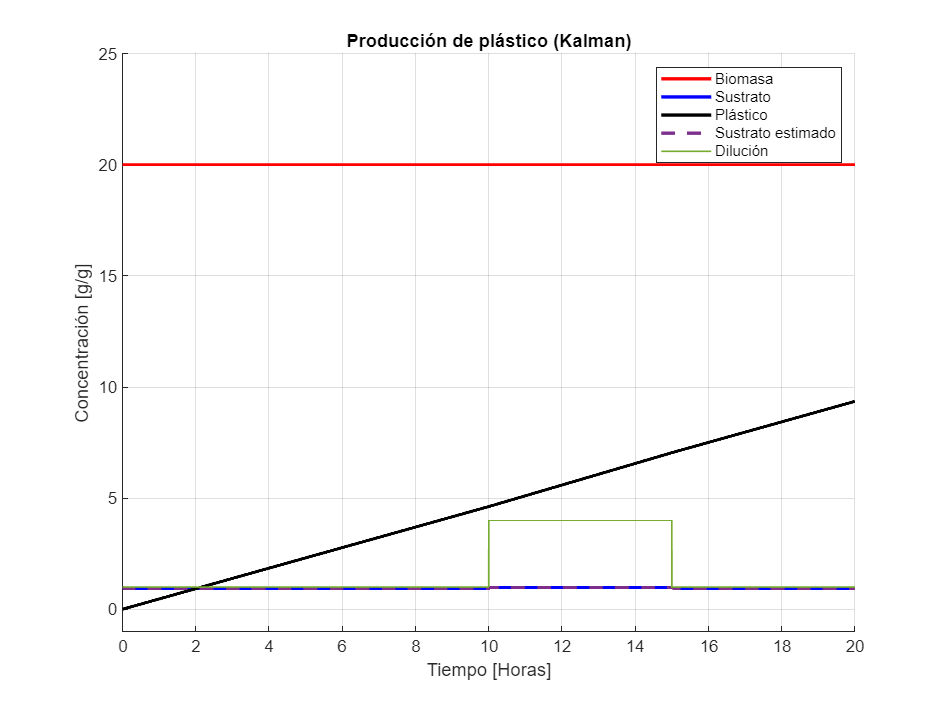

R_estimator_params.Kp1 = kp1;
R_estimator_params.qmax = qp_max;
R_estimator_params.kips = Kips;
R_estimator_params.kps = Kps;
R0=ones(2,2)*-1; % CI de la matriz R

estimatedModelParameters.K = [-ks2;1];
estimatedModelParameters.rp_params = modelParameters.rp_params;
estimatedModelParameters.Kipn = modelParameters.Kipn;

x0=20;
s0=1;
n0=0;
p0=0;
xi_in = [x0; s0; n0; p0];
D=20;
L=[0 1];

Poles=[1];
estimated_sustrate=cell(length(Poles));
error=cell(length(Poles));
MSE=cell(length(Poles));
for i=1:length(Poles)

    sim_out = sim('TP2Kalman', simConfig);
    
    time = sim_out.tout;
    biomass = sim_out.x.Data;
    sustrate = sim_out.s.Data;
    nitrogen = sim_out.n.Data;
    plastic = sim_out.p.Data;
    mu = sim_out.mu.Data;
    qp = sim_out.qp.Data;
    volume = sim_out.v.Data;
    Do = sim_out.Do.Data/D;
    estimated_states = sim_out.estimated_states.Data;
    % estimated_sustrate{i} = reshape(estimated_states(1,1,:), size(time));
    estimated_sustrate{i} = reshape(estimated_states(:,1), size(time));
    error{i}=(estimated_sustrate{i}-sustrate);
    MSE{i} = immse(estimated_sustrate{i}, sustrate);

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Producción de plástico (Kalman)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
ylim([-1 25])
plot(time, biomass, 'r', 'LineWidth', 2);
plot(time, sustrate, 'b', 'LineWidth', 2);
plot(time, plastic, 'k', 'LineWidth', 2);
plot(time, estimated_sustrate{1}, '--', 'LineWidth', 2);
plot(time, Do, 'LineWidth', 1);

legend('Biomasa', 'Sustrato', 'Plástico', 'Sustrato estimado', 'Dilución');

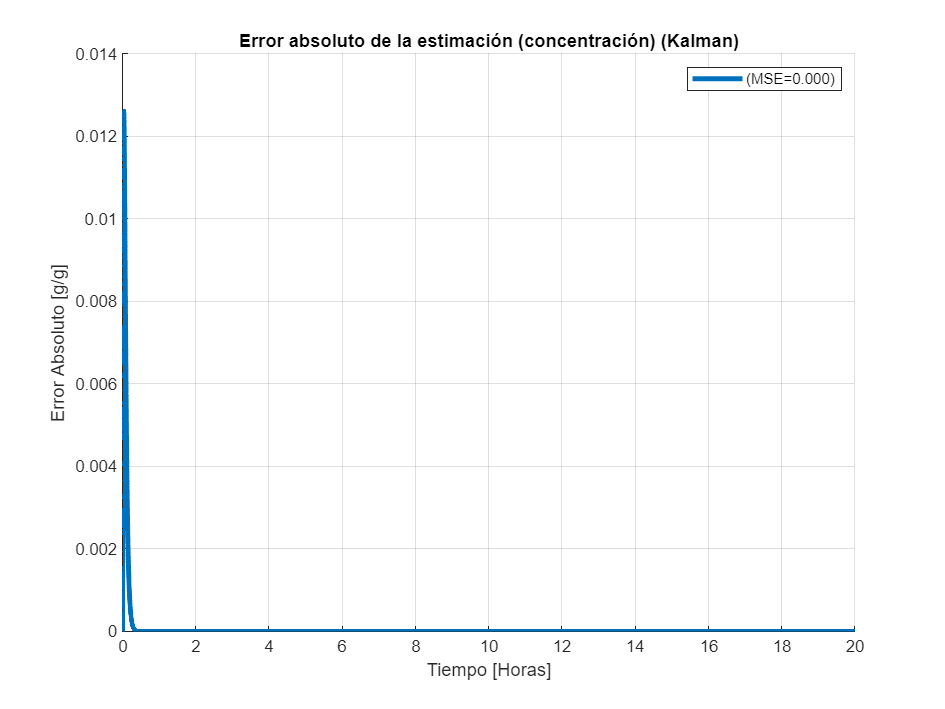


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error absoluto de la estimación (concentración) (Kalman)');
xlabel('Tiempo [Horas]');
ylabel('Error Absoluto [g/g]');
plot(time, abs(error{1}), 'LineWidth', 3);

legend(sprintf('(MSE=%.3f)', MSE{1}));

## Observador asintótico

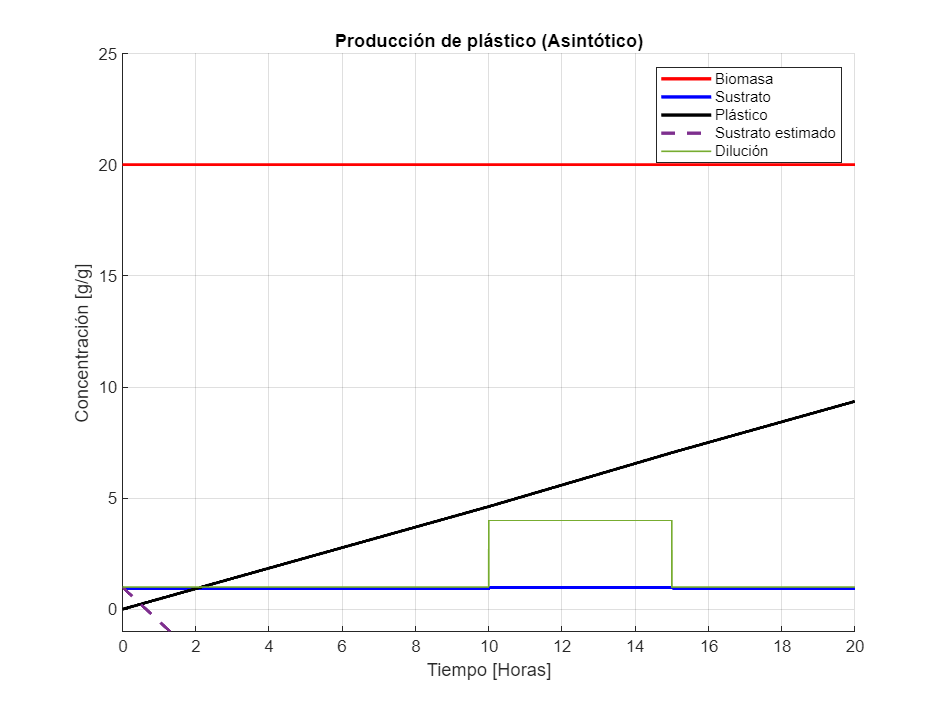

x0=20;
s0=1;
n0=0;
p0=0;
xi_in = [x0; s0; n0; p0];
D=20;
L=[0 1];

params.Ks2 = ks2;
params.s_in = s0;
z0=1;

estimatedModelParameters.K = [-ks2;1];
estimatedModelParameters.rp_params = modelParameters.rp_params;
estimatedModelParameters.Kipn = modelParameters.Kipn;

Poles=[1];
estimated_sustrate=cell(length(Poles));
error=cell(length(Poles));
MSE=cell(length(Poles));
for i=1:length(Poles)

    sim_out = sim('TP2Asintotico', simConfig);
    
    time = sim_out.tout;
    biomass = sim_out.x.Data;
    sustrate = sim_out.s.Data;
    nitrogen = sim_out.n.Data;
    plastic = sim_out.p.Data;
    mu = sim_out.mu.Data;
    qp = sim_out.qp.Data;
    volume = sim_out.v.Data;
    Do = sim_out.Do.Data/D;
    estimated_states = sim_out.estimated_states.Data;
    % estimated_sustrate{i} = reshape(estimated_states(1,1,:), size(time));
    estimated_sustrate{i}=estimated_states;
    error{i}=(estimated_sustrate{i}-sustrate);
    MSE{i} = immse(estimated_sustrate{i}, sustrate);

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Producción de plástico (Asintótico)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
ylim([-1 25])
plot(time, biomass, 'r', 'LineWidth', 2);
plot(time, sustrate, 'b', 'LineWidth', 2);
plot(time, plastic, 'k', 'LineWidth', 2);
plot(time, estimated_sustrate{1}, '--', 'LineWidth', 2);
plot(time, Do, 'LineWidth', 1);

legend('Biomasa', 'Sustrato', 'Plástico', 'Sustrato estimado', 'Dilución');

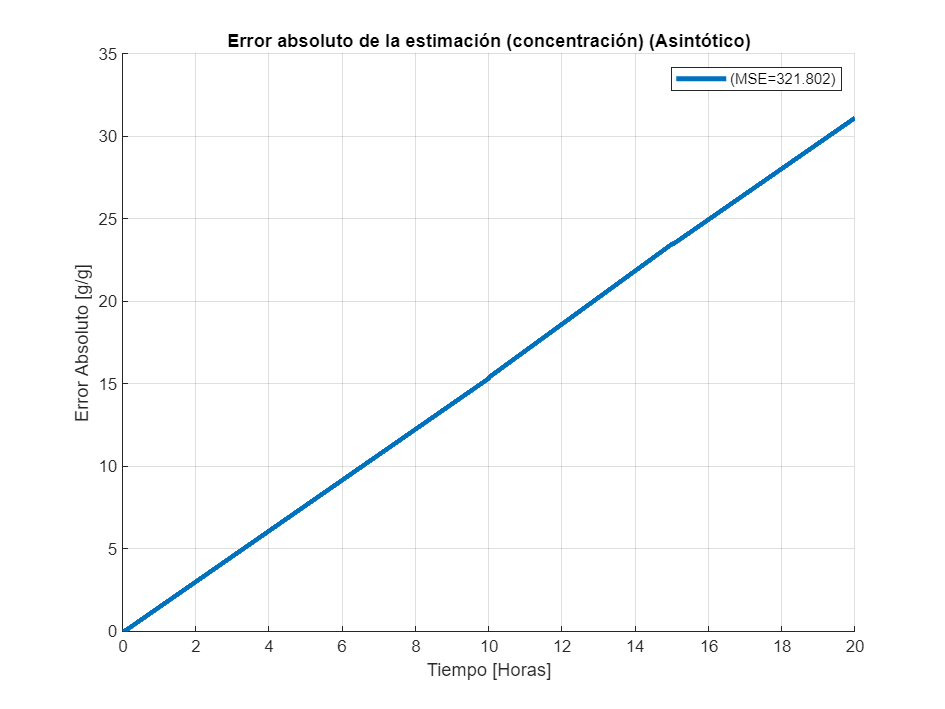


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error absoluto de la estimación (concentración) (Asintótico)');
xlabel('Tiempo [Horas]');
ylabel('Error Absoluto [g/g]');
plot(time, abs(error{1}), 'LineWidth', 3);

legend(sprintf('(MSE=%.3f)', MSE{1}));

Ahora hago lo mismo pero considero el sistema "completo" de 4 estados

x0=20;
s0=1;
n0=0;
p0=0;
xi_in = [x0; s0; n0; p0];
D=20;
L=[0 1];

params.Ks2 = ks2;
params.s_in = s0;
z0=1;

estimatedModelParameters.K = [-ks2;1];
estimatedModelParameters.rp_params = modelParameters.rp_params;
estimatedModelParameters.Kipn = modelParameters.Kipn;

Poles=[1];
estimated_sustrate=cell(length(Poles));
error=cell(length(Poles));
MSE=cell(length(Poles));
for i=1:length(Poles)

    sim_out = sim('TP2Asintotico2', simConfig);
    
    time = sim_out.tout;
    biomass = sim_out.x.Data;
    sustrate = sim_out.s.Data;
    nitrogen = sim_out.n.Data;
    plastic = sim_out.p.Data;
    mu = sim_out.mu.Data;
    qp = sim_out.qp.Data;
    volume = sim_out.v.Data;
    Do = sim_out.Do.Data/D;
    estimated_states = sim_out.estimated_states.Data;
    % estimated_sustrate{i} = reshape(estimated_states(1,1,:), size(time));
    estimated_sustrate{i}=estimated_states;
    error{i}=(estimated_sustrate{i}-sustrate);
    MSE{i} = immse(estimated_sustrate{i}, sustrate);

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Producción de plástico (Asintótico)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
ylim([-1 25])
plot(time, biomass, 'r', 'LineWidth', 2);
plot(time, sustrate, 'b', 'LineWidth', 2);
plot(time, plastic, 'k', 'LineWidth', 2);
plot(time, estimated_sustrate{1}, '--', 'LineWidth', 2);
plot(time, Do, 'LineWidth', 1);

legend('Biomasa', 'Sustrato', 'Plástico', 'Sustrato estimado', 'Dilución');

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error absoluto de la estimación (concentración) (Asintótico)');
xlabel('Tiempo [Horas]');
ylabel('Error Absoluto [g/g]');
plot(time, abs(error{1}), 'LineWidth', 3);

legend(sprintf('(MSE=%.3f)', MSE{1}));